clear
clc
close all

syms s Kp Ki Kd a b m

% Planta
P = (b/m)/(s + a/m);

% Controlador PID
C = Kp + Ki/s + Kd*s;

% Función de transferencia de lazo cerrado
Hc = simplify( (C*P) / (1 + C*P) )

$$Hc = \frac{b\,\left(\mathrm{Kd}\,s^{2}+\mathrm{Kp}\,s+\mathrm{Ki}\right)}{\mathrm{Ki}\,b+a\,s+m\,s^{2}+\mathrm{Kp}\,b\,s+\mathrm{Kd}\,b\,s^{2}}$$

Buscamos hacer esto:

syms w z

poli = (m+Kd*b)*s^2 + (Kp*b+a)*s + Ki*b == s^2 + 2*w*z*s + w^2 

$$poli = \left(m+\mathrm{Kd}\,b\right)\,s^{2}+\left(a+\mathrm{Kp}\,b\right)\,s+\mathrm{Ki}\,b=s^{2}+2\,z\,s\,w+w^{2}$$

Con números:

w = 30; %rad/s
z = 1; %factor de amortiguamiento relativo
a = 200;
b = 10000;
m = 1000;

S = solve(m + Kd*b == 1, a+ Kp*b == 2*z*w , Ki*b == w^2);
Kp = double(S.Kp)

Kp = -0.0140

Ki =  double(S.Ki)

Ki = 0.0900

Kd =  double(S.Kd)

Kd = -0.0999

Veamos la respuesta a un step y los polos y ceros

num = b*[Kd Kp Ki]

num =   -999  -140   900


den = [m+Kd*b Kp*b+a Ki*b]

den =      1    60   900


printsys(num,den);

 
num/den = 
 
   -999 s^2 - 140 s + 900
   ----------------------
      s^2 + 60 s + 900


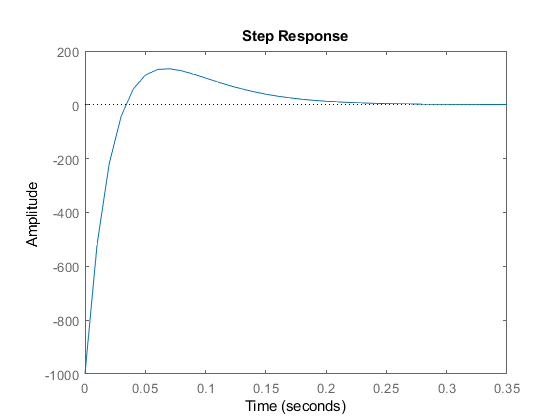

sys = tf(num,den);


step(sys);

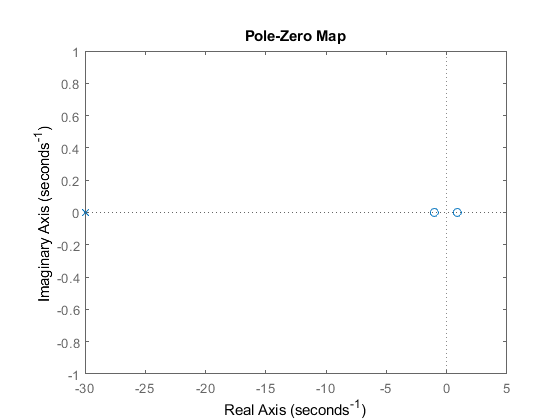

pzmap(sys);